# Exploring Sequential Gaussian Simulation

This script will let you explore how to use this package, what are the parametrization and what are the difference among the various SGS algorithm possible

## Parametrization

nx = 50; % number of cell along x
ny = 50; % number of cell along y

m = 1; % number of realization

covar.model = 'gaussian'; % type of covariance function, see functions/kriginginitiaite.m for option
covar.range0 = [10 10]; % range of covariance [y x]
covar.azimuth = 0; % orientation of the covariance
covar.c0 = 1; % variance
covar.alpha = 1; % parameter of covariance function (facult)

parm.saveit = false; % save in a file
parm.seed_path = 'shuffle'; % seed for the path
parm.seed_search = 'shuffle'; % seed for the search (equal distance node)
parm.seed_U = 'shuffle'; % seed of the node value sampling
parm.mg = 1 ; % multigrid vs randomized path

neigh.wradius = 3; % maximum range of neighboorhood search, factor of covar.range.
neigh.lookup = false; % lookup table.
neigh.nb = 40; % maximum number of neighborhood

method = 'trad'; % SGS method: cst_par, cst_par_cond, hybrid, varcovar

## Traditional SGS

Traditional SGS is the most intuitive way of coding SGS. 

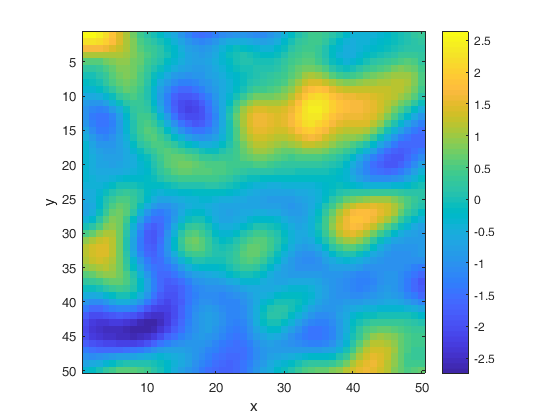

method = 'trad';
m=1;
[Rest, t1] = SGS(nx,ny,m,covar,neigh,parm, method);

figure;imagesc(Rest);
xlabel('x'); ylabel('y'); colorbar; axis equal tight;

However, traditional SGS scales very badly for multiple realization. 

m=10;
[Rest, t10] = SGS(nx,ny,m,covar,neigh,parm, method);
disp(['Time spend for 1 realizations: ' num2str(t1.global) 'sec'])

Time spend for 1 realizations: 2.7321sec


disp(['Time spend for 10 realizations: ' num2str(t10.global) 'sec'])

Time spend for 10 realizations: 16.4613sec


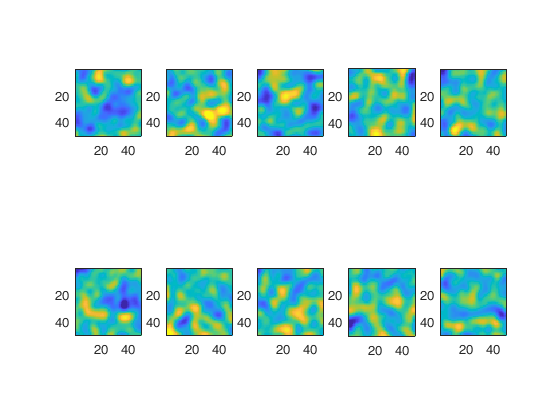

figure;
for i_m=1:m
    subplot(2,m/2,i_m); imagesc(Rest(:,:,i_m)); caxis([-3 3]); axis equal tight;
end

## Constant path

A very good solution is to use a lookup table.

neigh.lookup = true;
method = 'trad';
[~, t10] = SGS(nx,ny,m,covar,neigh,parm, method);
disp(['Time spend for 10 realizations with lookup table: ' num2str(t10.global) 'sec'])

Time spend for 10 realizations with lookup table: 7.2936sec


But when the grid get larger, lookup table can be difficult to store and not very efficient. Another solution is to use a constant path. This allows to reuse the same kriging weight for each realizations

neigh.lookup = false;
method = 'cst';
[Rest, t10] = SGS(nx,ny,m,covar,neigh,parm, method);
disp(['Time spend for 10 realizations with a constant path: ' num2str(t10.global) 'sec'])

Time spend for 10 realizations with a constant path: 2.2187sec


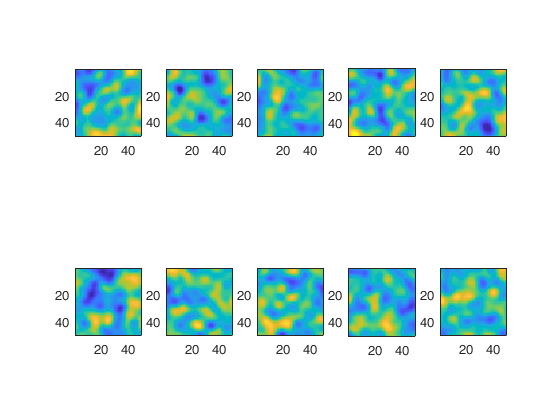

figure;
for i_m=1:m
    subplot(2,m/2,i_m); imagesc(Rest(:,:,i_m)); caxis([-3 3]); axis equal tight;
end

## Constant path with parralelization

method = 'cst_par';
m=50;
[Rest, t50] = SGS(nx,ny,m,covar,neigh,parm, method);
disp(['Time spend for 50 realizations with a parralelized constant path: ' num2str(t50.global) 'sec'])

Time spend for 50 realizations with a parralelized constant path: 3.8653sec


## Conditional SGS with a Parralelized constant path

We can also defined some conditional point 

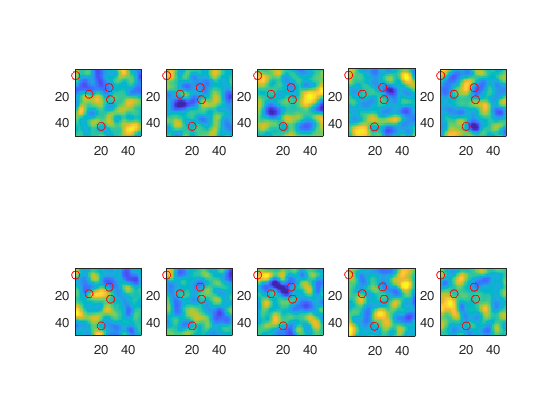

method='cst_par_cond';
m=10;
grid.x=1:nx;
grid.y=1:ny;
field=fftma_perso(covar, grid);
prim = sampling_pt(grid,field,2,5);

[Rest, t10] = SGS(nx,ny,m,covar,neigh,parm, method, prim);
for i_m=1:m
    subplot(2,m/2,i_m); hold on;caxis([-3 3]);axis equal tight;
    imagesc(Rest(:,:,i_m));  scatter(prim.x,prim.y,'or')
end

## Hybrid SGS

Hybrid allows to switch from a randomized path to a constant path at a certain level of the multigrid path. This level is defined by `parm.hybrid`

method='hybrid';
m=10;
for hybrid=1:7
    parm.hybrid = hybrid;
    [Rest, t10] = SGS(nx,ny,m,covar,neigh,parm, method);
    disp(['Time spend for 10 realizations with hybrid level ' num2str(parm.hybrid) ': ' num2str(t10.global) 'sec'])
end

Time spend for 10 realizations with hybrid level 1: 0.3981sec
Time spend for 10 realizations with hybrid level 2: 0.51953sec
Time spend for 10 realizations with hybrid level 3: 0.62911sec
Time spend for 10 realizations with hybrid level 4: 0.66717sec
Time spend for 10 realizations with hybrid level 5: 0.81922sec
Time spend for 10 realizations with hybrid level 6: 1.07sec
Time spend for 10 realizations with hybrid level 7: 1.6025sec


## Varcovar

Varcovar compute the actual full covariance matrix of the simulation. Have a look at the paper from Emery & Pelàez (2011) DOI:[10.1007/s10596-011-9235-5](https://link.springer.com/article/10.1007/s10596-011-9235-5) for more information.

method='varcovar';
[Rest, t10] = SGS(nx,ny,m,covar,neigh,parm, method);